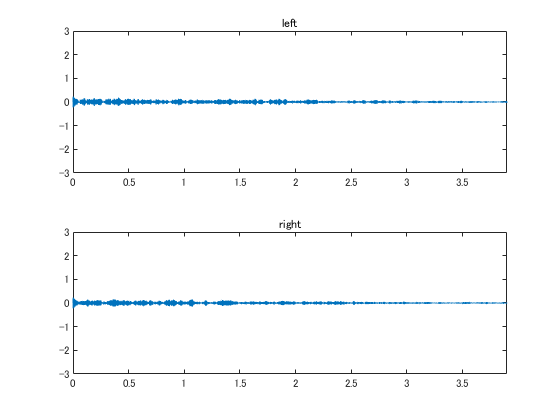

% ----------------
% general settings
% ----------------

% sampling freq
Fs = 44100;

% buffer size for main loop
BFSIZE = 1024;

p = Schroeders();

p.T      = 16.78;
p.drymix = 1;
p.wetmix = 0.6;
p.W      = 0;

% -------
% process 
% -------

% input audio file (& ajust the size);
X = [audioread("sound.wav");zeros(3*Fs,2)];
%X = [[1 1];zeros(3*Fs,2)];

nloop = floor(length(X)/BFSIZE)+1;
X((nloop)*BFSIZE,:) = [0;0];

% output matrix
Y = zeros(size(X));

% main loop
for i = 1:nloop
    % read buffer
    idxs = ((i-1)*BFSIZE+1):(i*BFSIZE);
    in = X(idxs,:);
    
    % process
    out = p.process(in);
    
    Y(idxs,:) = out;
end

% plot
T = ((1:length(X))-1)/Fs;figure;tiledlayout("flow");hold on
nexttile;plot(T,Y(:,1));subtitle("left");xlim([-inf,inf]);ylim([-3,3]);
nexttile;plot(T,Y(:,2));subtitle("right");xlim([-inf,inf]);ylim([-3,3]);


% sound
sound(X,Fs);
pause(1);
soundsc(Y,Fs);